**Comparison of network structures: training**

In this case a pretrained convolutional model and a fully connected model are trained using the LibriSpeech dataset (at 16 kHz - I need to test this on 8 kHz as well...)

Start by loading the pretrained convolutional network:

load preTrainConv.mat %convolutional pretrained model

load preTrainFull.mat %fully connected

Load the dataset - in this case, the open-source LibriSpeech, from my own folder:

dataset = fullfile("LibriSpeech"); 
trainDataVoices = audioDatastore(fullfile(dataset,"train-clean-100"),...
    "IncludeSubfolders",true);

samplesIncluded = 80; %load only a section of the dataset
trainDataVoices = shuffle(trainDataVoices);
trainDataVoices = subset(trainDataVoices,1:samplesIncluded);
fs = 16000; %to be extracted from data? -in case we use another dataset

TODO: The sample rate of this dataset is at 16 kHz, which is a higher bandwidth than we need in the case of speech. To spare more resources, the dataset should be probably be downsampled

load data for training into tall-array format

[noise, fsNoise] = audioread("WashingMachine-16-8-mono-1000secs.mp3");

audioData = readall(trainDataVoices);

%set values for data to be segmented
segments = 8;
window = sqrt(hann(256,'periodic')); %NOTICE: window is 256, input features will be 129
overlap = round(length(window)*0.5);

dftSize = length(window); 

T = tall(audioData); 

[targets, predictors, magnitudes] = cellfun(...
    @(x)prepare_data(x,...
        fs,...
        noise,...
        window,...
        overlap,...
        dftSize ...
        ), ...
    T, ...
    UniformOutput=false ...
); 

[targets, predictors, magnitudes] = gather(targets, predictors, magnitudes);

Evaluating tall expression using the Local MATLAB Session:
- Pass 1 of 1: Completed in 2 min 24 sec
Evaluation completed in 3 min 35 sec


predictors = cat(3,predictors{:});
noisyMean = mean(predictors(:));
noisyStd = std(predictors(:));
predictors(:) = (predictors(:) - noisyMean)/noisyStd;

targets = cat(2,targets{:});
cleanMean = mean(targets(:));
cleanStd = std(targets(:));
targets(:) = (targets(:) - cleanMean)/cleanStd;

%reshape
predictors = reshape(predictors,size(predictors,1),size(predictors,2),1,size(predictors,3));
targets = reshape(targets,1,1,size(targets,1),size(targets,2));

%% split into training and validation

features = dftSize*0.5;

inds = randperm(size(targets,4));
L = floor(0.90*size(targets,4));

trainPredictors = predictors(:,:,:,inds(1:L));
trainTargets = targets(:,:,:,inds(1:L));

validatePredictors = predictors(:,:,:,inds(L+1:end));
validateTargets = targets(:,:,:,inds(L+1:end));

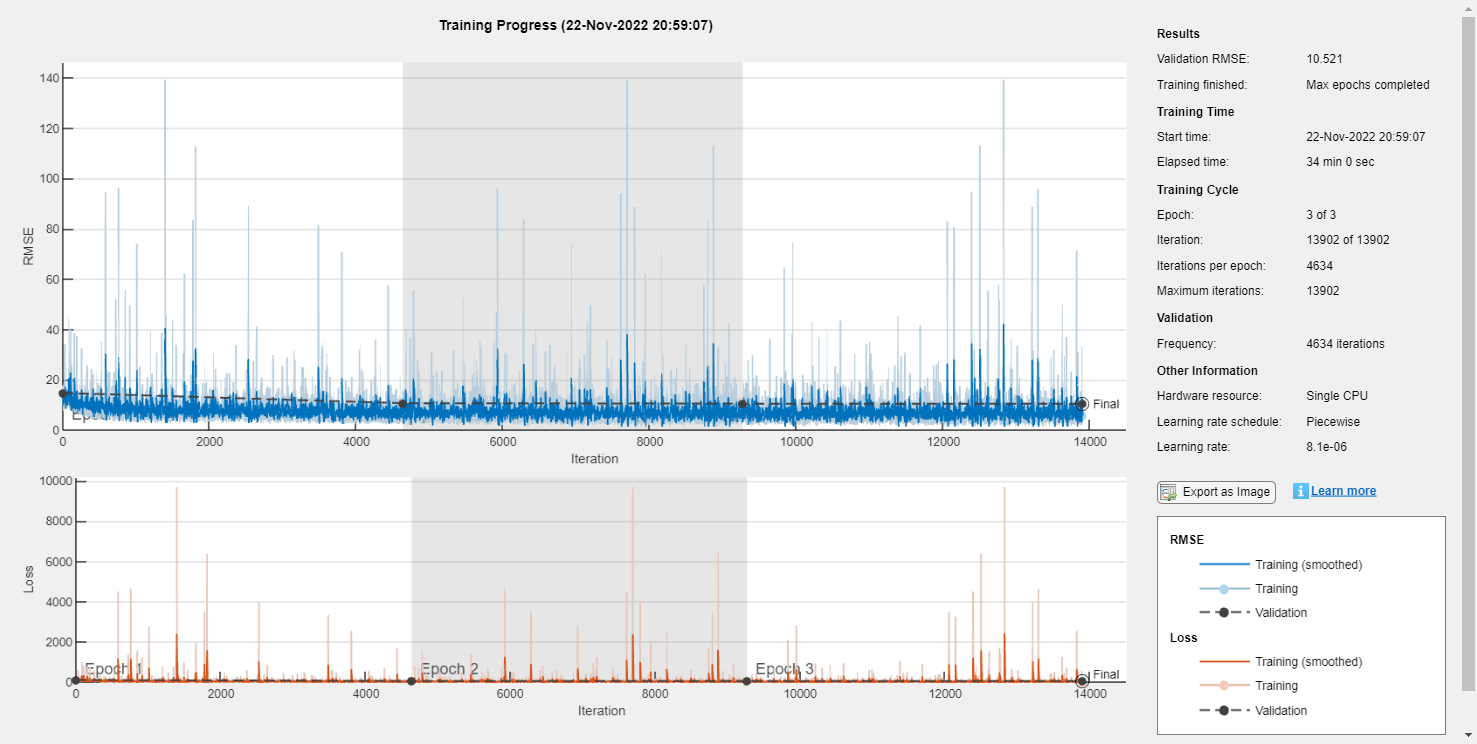

miniBatchSize = floor(samplesIncluded*0.30);
options = trainingOptions("adam", ...
    MaxEpochs=3, ...
    InitialLearnRate=1e-5, ...
    MiniBatchSize=miniBatchSize, ...
    Shuffle="every-epoch", ...
    Plots="training-progress", ...
    Verbose=false, ...
    ValidationFrequency=floor(size(trainPredictors,4)/miniBatchSize), ...
    LearnRateSchedule="piecewise", ...
    LearnRateDropFactor=0.9, ... 
    LearnRateDropPeriod=1, ...
    ... %ValidationData={validatePredictors,permute(validateTargets,[3 1 2 4])});
    ValidationData={validatePredictors,validateTargets});

%% Train the convolutional network

    convNet = trainNetwork(...
        trainPredictors, ...
        permute(trainTargets,[3 1 2 4]), ...
        denoiseNetFullyConvolutional.Layers, ...
        options ...
    );

Train the fully connected network:

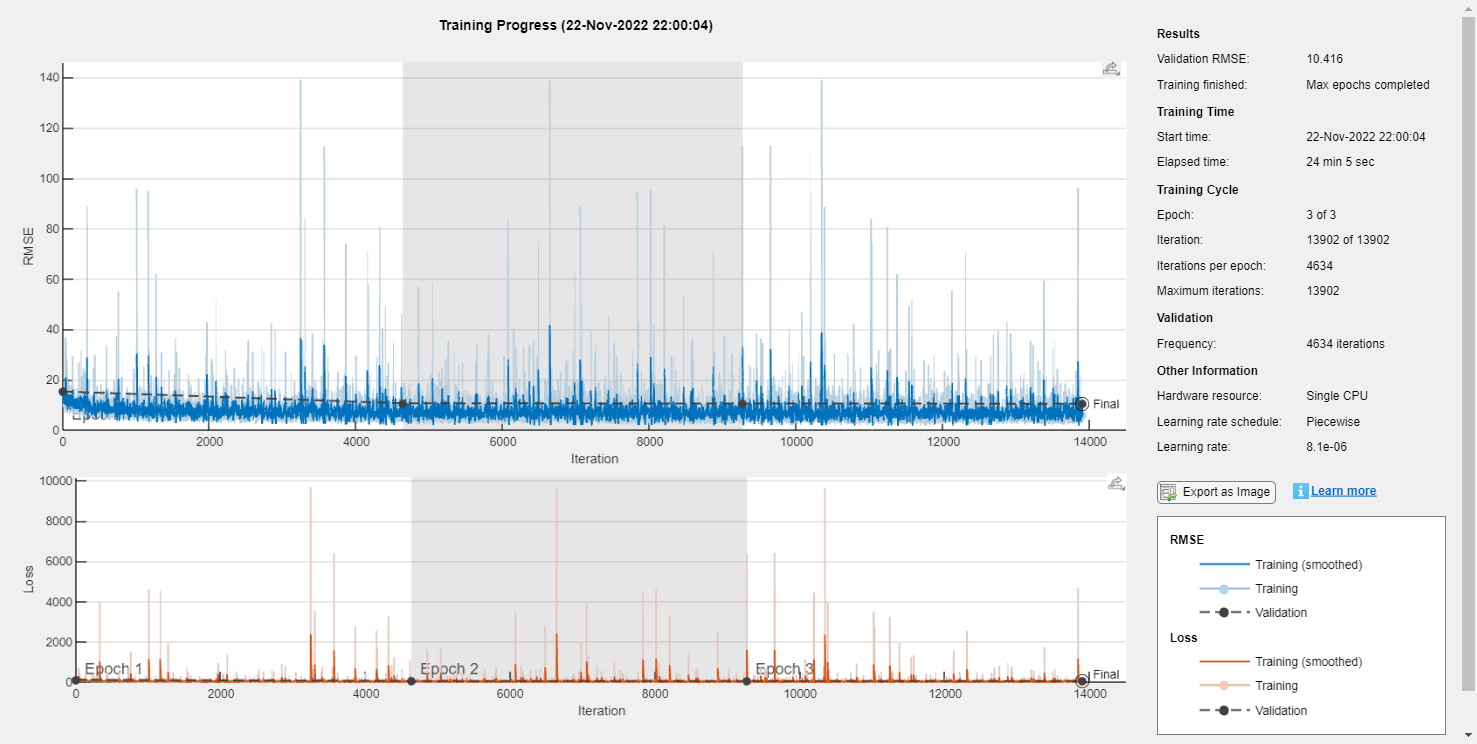

miniBatchSize = floor(samplesIncluded*0.30);
options = trainingOptions("adam", ...
    MaxEpochs=3, ...
    InitialLearnRate=1e-5, ...
    MiniBatchSize=miniBatchSize, ...
    Shuffle="every-epoch", ...
    Plots="training-progress", ...
    Verbose=false, ...
    ValidationFrequency=floor(size(trainPredictors,4)/miniBatchSize), ...
    LearnRateSchedule="piecewise", ...
    LearnRateDropFactor=0.9, ... 
    LearnRateDropPeriod=1, ...
    ValidationData={validatePredictors,permute(validateTargets,[3 1 2 4])});

    fullNet = trainNetwork(...
        trainPredictors, ...
        trainTargets, ...
        denoiseNetFullyConnected.Layers, ...
        options ...
    );